clear all;
clc;
run('LabA_LoadPhysicalParameters.m')

loading the physical parameters...done


fSamplingPeriod = 0.0100;
save('LAB_B.mat','fSamplingPeriod','-append')


GAMMA = [(I_w+(m_w*(l_w^2))+(m_b*l_w^2)) (m_b*(l_w^2)*l_b); (m_b*l_b) (I_b+(m_b*(l_b^2)))];
ALPHA = [ 0 (-K_e*K_t)/R_m 0 (l_w*K_e*K_t)/R_m; 0 ((K_e*K_t)/(R_m*l_w)) (m_b*l_b*g) -(K_e*K_t)/R_m];
BETA = [ ((l_w*K_t)/R_m); -K_t/R_m];


A = GAMMA\ALPHA

A = 	1.0e+03 *

         0   -0.4350   -0.0061    0.0091
         0    1.9034    0.0620   -0.0400


A = [0 1 0 0;A(1,:);0 0 0 1;A(2,:)]

A = 	1.0e+03 *

         0    0.0010         0         0
         0   -0.4350   -0.0061    0.0091
         0         0         0    0.0010
         0    1.9034    0.0620   -0.0400


B = GAMMA\BETA

B =    20.5759
  -90.0275


B = [0;B(1,:);0;B(2,:)]

B =          0
   20.5759
         0
  -90.0275



C = [0 0 1 0];
D = 0;

G = ss(A,B,C,D);
[b,a] = ss2tf(A,B,C,D)

b =          0         0  -90.0275    0.0000   -0.0000


a = 	1.0e+04 *

    0.0001    0.0475   -0.0062   -1.5371         0


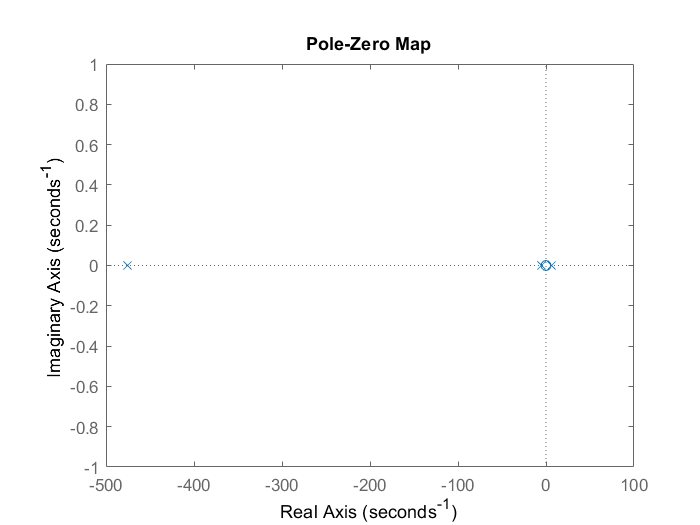

pzplot(G)


[z,p,k] = zpkdata(G,'v')

z = 0

p =  -475.0690
   -5.6571
    5.7195


k = -90.0275

G_tf = zpk(z,p,k)


G_tf =
 
           -90.028 s
  ----------------------------
  (s+475.1) (s+5.657) (s-5.72)
 
Continuous-time zero/pole/gain model.



G_new = zpk(z,p(1:2),k)


G_new =
 
       -90.028 s
  -------------------
  (s+475.1) (s+5.657)
 
Continuous-time zero/pole/gain model.



G_new1 = zpk(z,p(2:3),k)


G_new1 =
 
      -90.028 s
  ------------------
  (s+5.657) (s-5.72)
 
Continuous-time zero/pole/gain model.



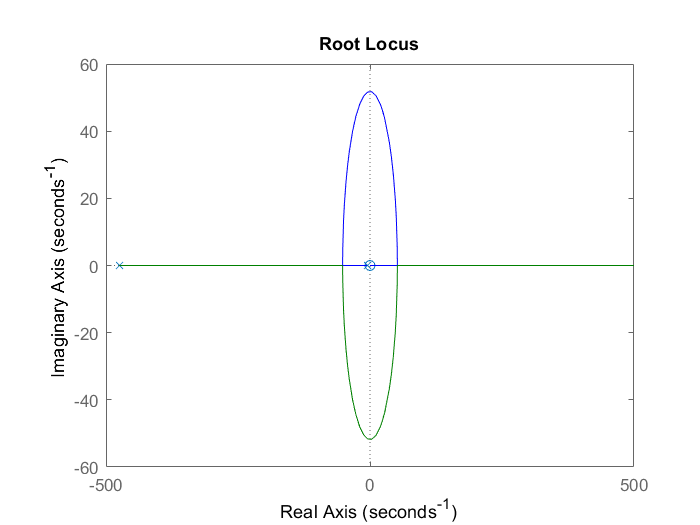

%controlSystemDesigner(G_tf);

rlocus(G_new);


p_new = -3;
kP=(p(1)*p_new+p(2)*p_new-p(1)*p(3)-p(2)*p(3))/k

kP = -46.5603

kI=(p(1)*p(2)*p(3)-p(1)*p(2)*p_new)/k

kI = -260.2962

kD=(p(3)-p_new)/k

kD = -0.0969

save('LAB_B.mat','kD','kI','kP','-append');

BETA = [l_w*K_t/R_m l_w^2; -K_t/R_m l_b];


A_new = GAMMA\ALPHA;
A_new = [0 1 0 0;A_new(1,:);0 0 0 1;A_new(2,:)]

A_new = 	1.0e+03 *

         0    0.0010         0         0
         0   -0.4350   -0.0061    0.0091
         0         0         0    0.0010
         0    1.9034    0.0620   -0.0400


B_for_poking = GAMMA\BETA

B_for_poking =    20.5759    2.1054
  -90.0275    2.0256


B_for_poking = [0 0;B_for_poking(1,:);0 0;B_for_poking(2,:)]

B_for_poking =          0         0
   20.5759    2.1054
         0         0
  -90.0275    2.0256



C_for_full_observability = [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]

C_for_full_observability =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_for_full_observability_and_poking = [0 0; 0 0;0 0;0 0;]

D_for_full_observability_and_poking =      0     0
     0     0
     0     0
     0     0



GN = ss(A_new,B_for_poking,C_for_full_observability,D_for_full_observability_and_poking)


GN =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0    -435  -6.099   9.136
   x3       0       0       0       1
   x4       0    1903   62.02  -39.97
 
  B = 
           u1      u2
   x1       0       0
   x2   20.58   2.105
   x3       0       0
   x4  -90.03   2.026
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.



TF_GN = tf(GN)


TF_GN =
 
  From input 1 to output...
                  20.58 s^2 - 727
   1:  --------------------------------------
       s^4 + 475 s^3 - 62.02 s^2 - 1.537e04 s
 
         20.58 s^2 + 1.828e-14 s - 727
   2:  ----------------------------------
       s^3 + 475 s^2 - 62.02 s - 1.537e04
 
                    -90.03 s
   3:  ----------------------------------
       s^3 + 475 s^2 - 62.02 s - 1.537e04
 
                   -90.03 s^2
   4:  ----------------------------------
       s^3 + 475 s^2 - 62.02 s - 1.537e04
 
  From input 2 to output...
            2.105 s^2 + 102.7 s - 142.9
   1:  --------------------------------------
       s^4 + 475 s^3 - 62.02 s^2 - 1.537e04 s
 
          2.105 s^2 + 102.7 s - 142.9
   2:  ----------------------------------
       s^3 + 475 s^2 - 62.02 s - 1.537e04
 
                 2.026 s + 4889
   3:  ----------------------------------
       s^3 + 475 s^2 - 62.02 s - 1.537e04
 
         2.026 s^2 + 4889 s - 8.04e-12
   4:  ---------------------------

%For PID N = 10000
N = 10000;

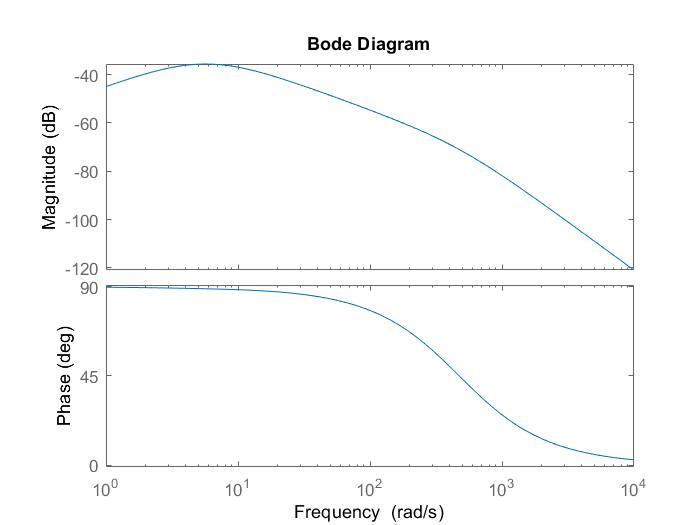

bode(G_tf)

s = tf('s');
PID_c = kP+(kI/s)+(kD*(N/(1+(N/s))))


PID_c =
 
  -1015 s^2 - 4.659e05 s - 2.603e06
  ---------------------------------
            s^2 + 10000 s
 
Continuous-time transfer function.



% [z,p,k] = zpkdata(PID_c,'v')
% TF_PID_c = zpk(z,p,k)
Ts = 0.01;

Cs = feedback(PID_c*G_tf,1)


Cs =
 
      91387 s (s+453.3) (s+5.657)
  ------------------------------------
  s (s+9991) (s+475.5) (s+5.657) (s+3)
 
Continuous-time zero/pole/gain model.




%c2d(PID_c, Ts)

LAB B

Checking for controllabitlity and Observabitlity

Co = ctrb(A,B)

Co = 	1.0e+09 *

         0    0.0000   -0.0000    0.0046
    0.0000   -0.0000    0.0046   -2.2058
         0   -0.0000    0.0000   -0.0203
   -0.0000    0.0000   -0.0203    9.6527


Ob_mat = obsv(A,C)

Ob_mat = 	1.0e+05 *

         0         0    0.0000         0
         0         0         0    0.0000
         0    0.0190    0.0006   -0.0004
         0   -9.0415   -0.1409    0.1905


rank(Co)

ans = 4

rank(Ob_mat)

ans = 3

%Not fully observable as rank < 4
G_tf


G_tf =
 
           -90.028 s
  ----------------------------
  (s+475.1) (s+5.657) (s-5.72)
 
Continuous-time zero/pole/gain model.



Creating state controller

%poles are
p

p =  -475.0690
   -5.6571
    5.7195


p2_new = -3.1

p2_new = -3.1000

p3_new = -3

p3_new = -3

p4_new = -3.01

p4_new = -3.0100

p_control = [p(1) p2_new p3_new p4_new]

p_control =  -475.0690   -3.1000   -3.0000   -3.0100


K = place(A,B,p_control)

K =   -18.2919  -39.2563  -53.2496   -9.0740


save('LAB_B.mat','K','-append')

Creating state observers 

p_observe = [p(1,1);p(2:3,1).*5]

p_observe =  -475.0690
  -28.2855
   28.5977


p_observe = [p_observe(1:2,1) ;-1*(p_observe(3,1));p_observe(2,1)]

p_observe =  -475.0690
  -28.2855
  -28.5977
  -28.2855


C_Lcontrol = [1 0 0 0;0 0 1 0]

C_Lcontrol =      1     0     0     0
     0     0     1     0


L = place(A',C_Lcontrol',p_observe)'

L =    28.2994    0.5872
   -0.1642   16.7632
    0.6042   56.9316
   19.5392  844.9284


save('LAB_B.mat','L','-append')

%reduced order observer

n  = 4;
p = 1;
Iden_4 = eye(4)

Iden_4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


C_acc = Iden_4(1,:); % First row is C_acc
C_acc_bar = Iden_4(3,:); % Second row is C_acc_bar


V = [0 1 0 0 ;0 0 1 0;0 0 0 1]; % Dimensions n-p x n = 2x4

T_inv = vertcat(C_acc,V);
T = T_inv^-1;
% C_acc_t =  horzcat(eye(p), zeros(p,n-p));
%
%
% C_V = (C_acc_t * C^-1)^-1;



A_t = T_inv * A * T;
B_t = T_inv * B;
C_acc_t = C_acc * T;
C_acc_bar_t = C_acc_bar * T;

A_yy_t = A_t(1:p,1:p);
A_yx_t = A(1:p,p+1:n);
A_xy_t = A(p+1:n,1:p);
A_xx_t = A(p+1:n,p+1:n);

C_acc_bar_t_x = C_acc_bar_t(:,p+1:n)

C_acc_bar_t_x =      0     1     0


C_acc_bar_t_y = C_acc_bar_t(:,1:p)

C_acc_bar_t_y = 0

B_t_x = B_t(p+1:n,:)

B_t_x =    20.5759
         0
  -90.0275


B_t_y = B_t(1:p,:)

B_t_y = 0


L_reduced_obs = place(A_xx_t',[A_yx_t;C_acc_bar_t_x]',p_observe(1:n-p))'

L_reduced_obs = 	1.0e+03 *

    0.0230    0.0417
    0.0478    0.0339
    1.3536    0.0009


L_reduced_obs_acc = L_reduced_obs(:,1:p)

L_reduced_obs_acc = 	1.0e+03 *

    0.0230
    0.0478
    1.3536


L_reduced_obs_Nacc = L_reduced_obs(:,p+1)

L_reduced_obs_Nacc =    41.6578
   33.9131
    0.9258





M1 = (A_xx_t - (L_reduced_obs_acc*A_yx_t) - (L_reduced_obs_Nacc*C_acc_bar_t_x))

M1 =  -458.0668  -47.7569    9.1357
  -47.8216  -33.9131    1.0000
  549.7949   61.0935  -39.9722


M2 = (B_t_x - (L_reduced_obs_acc*B_t_y))

M2 =    20.5759
         0
  -90.0275


M3 = (A_xy_t - L_reduced_obs_acc*A_yy_t - L_reduced_obs_Nacc*C_acc_bar_t_y)

M3 =      0
     0
     0


M4 = L_reduced_obs_Nacc

M4 =    41.6578
   33.9131
    0.9258


M5 = L_reduced_obs_acc

M5 = 	1.0e+03 *

    0.0230
    0.0478
    1.3536




M6 = [1 0 0 0]'

M6 =      1
     0
     0
     0


M7 = [0 0 0;1 0 0;0 1 0;0 0 1]

M7 =      0     0     0
     1     0     0
     0     1     0
     0     0     1


C = C_Lcontrol;
save('LAB_B.mat','M1','M2','M3','M4','M5','M6','M7','-append')
save('LAB_B.mat','A','B','C','D','-append')

Discretizing the state controllers and observers

G_disc = c2d(G,fSamplingPeriod);
[Ad,Bd,Cd,Dd] = ssdata(G_disc)

Ad =     1.0000    0.0028   -0.0001    0.0002
         0    0.0918   -0.0074    0.0190
         0    0.0317    1.0021    0.0093
         0    3.9783    0.3858    0.9186


Bd =     0.0003
    0.0430
   -0.0015
   -0.1882


Cd =      0     0     1     0


Dd = 0

p_control_disc = exp((p_control*fSamplingPeriod))

p_control_disc =     0.0086    0.9695    0.9704    0.9703


p_observe_disc = exp((p_observe*fSamplingPeriod))

p_observe_disc =     0.0086
    0.7536
    0.7513
    0.7536



%Discretizing state controller
Kd = place(Ad,Bd,p_control_disc)

Kd =   -17.4693  -38.5304  -52.4370   -8.9068


save('LAB_B.mat','Kd','-append')

C_fullcontrol_dis = [1 0 0 0;0 0 1 0]

C_fullcontrol_dis =      1     0     0     0
     0     0     1     0


Ld = place(Ad',C_fullcontrol_dis',p_observe_disc)'

Ld =     0.2465    0.0051
    0.0074    0.1309
    0.0054    0.4989
    0.1131    6.5517


save('LAB_B.mat','Ld','-append')

%% Reduced observer
C_acc_dis = Iden_4(1,:); % First row is C_acc
C_acc_bar_dis = Iden_4(3,:); % Second row is C_acc_bar

A_t_dis = T_inv * Ad * T;
B_t_dis = T_inv * Bd;
C_acc_t_dis = C_acc_dis * T;
C_acc_bar_t_dis = C_acc_bar_dis * T;

A_yy_t_dis = A_t_dis(1:p,1:p);
A_yx_t_dis = Ad(1:p,p+1:n);
A_xy_t_dis = Ad(p+1:n,1:p);
A_xx_t_dis = Ad(p+1:n,p+1:n);

C_acc_bar_t_x_dis = C_acc_bar_t_dis(:,p+1:n)

C_acc_bar_t_x_dis =      0     1     0


C_acc_bar_t_y_dis = C_acc_bar_t_dis(:,1:p)

C_acc_bar_t_y_dis = 0

B_t_x_dis = B_t_dis(p+1:n,:)

B_t_x_dis =     0.0430
   -0.0015
   -0.1882


B_t_y_dis = B_t_dis(1:p,:)

B_t_y_dis = 3.4281e-04


L_reduced_obs_dis = place(A_xx_t_dis',[A_yx_t_dis;C_acc_bar_t_x_dis]',p_observe_disc(1:n-p))'

L_reduced_obs_dis = 	1.0e+03 *

    0.0192    0.0001
    0.0476    0.0003
    1.1903    0.0004


L_reduced_obs_acc_dis = L_reduced_obs_dis(:,1:p)

L_reduced_obs_acc_dis = 	1.0e+03 *

    0.0192
    0.0476
    1.1903


L_reduced_obs_Nacc_dis = L_reduced_obs_dis(:,p+1)

L_reduced_obs_Nacc_dis =     0.0987
    0.2692
    0.3770



Md1 = (A_xx_t_dis - (L_reduced_obs_acc_dis*A_yx_t_dis) - (L_reduced_obs_Nacc_dis*C_acc_bar_t_x_dis))

Md1 =     0.0390   -0.1046    0.0161
   -0.0993    0.7367    0.0021
    0.7026    0.1029    0.7378


Md2 = (B_t_x_dis - (L_reduced_obs_acc_dis*B_t_y_dis))

Md2 =     0.0364
   -0.0178
   -0.5962


Md3 = (A_xy_t_dis - L_reduced_obs_acc_dis*A_yy_t_dis - L_reduced_obs_Nacc_dis*C_acc_bar_t_y_dis)

Md3 = 	1.0e+03 *

   -0.0192
   -0.0476
   -1.1903


Md4 = L_reduced_obs_Nacc_dis

Md4 =     0.0987
    0.2692
    0.3770


Md5 = L_reduced_obs_acc_dis

Md5 =     0.0192
    0.0476
    1.1903




Md6 = [1 0 0 0]'

Md6 =      1
     0
     0
     0


Md7 = [0 0 0;1 0 0;0 1 0;0 0 1]

Md7 =      0     0     0
     1     0     0
     0     1     0
     0     0     1



save('LAB_B.mat','Md1','Md2','Md3','Md4','Md5','Md6','Md7','-append')
save('LAB_B.mat','Ad','Bd','Cd','Dd','-append')

LAB C

Part 2

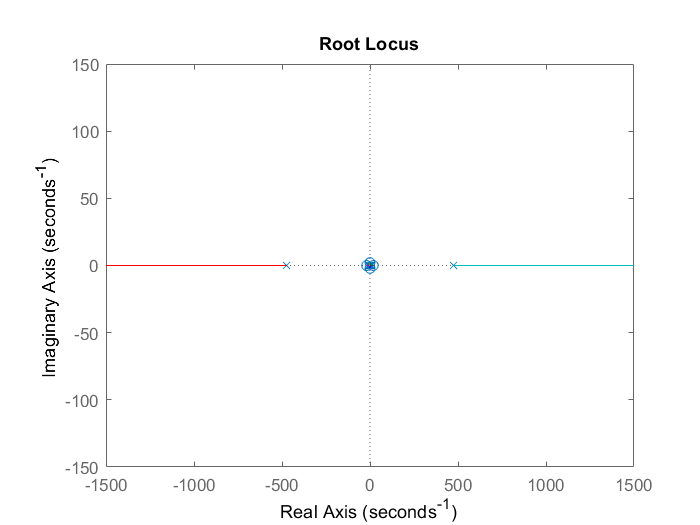

ro = 1;
C_bar = [50 1 100 5];
C = [0 0 1 0];
% bigA=[A zeros(size(A)); -C_bar'*C_bar -A']
% bigB=[B; -C_bar'*D]
% bigC=[D'*C_bar B']
% bigD=D'*D
%  
% srlsys=ss(bigA,bigB,bigC,bigD);
% rlocus(srlsys);
[b,a] = ss2tf(A,B,C_bar,D,1);
b_neg = b;
b_neg(2:2:end) = -b_neg(2:2:end);
a_neg = a;
a_neg(2:2:end) = -a_neg(2:2:end);
tf_rootlocus = tf(b,a)*tf(b_neg,a_neg);
rlocus(tf_rootlocus);

ro = 0.0161;   %By inspecton of root locus
lqr_roots = rlocus(tf_rootlocus,ro)

lqr_roots =  -478.1818
  478.1818
   -6.8862
    6.8862
   -4.5602
    4.5602
   -0.3072
    0.3072


p_control_lqr = [lqr_roots(1),lqr_roots(3),lqr_roots(5),lqr_roots(6)]

p_control_lqr =  -478.1818   -6.8862   -4.5602    4.5602


K_lqr = place(A,B,p_control_lqr)

K_lqr =    94.1866   -7.2683  -15.5074   -1.7729


save('LAB_B.mat', 'K_lqr','-append')

Part 3

fSamplingPeriod_old = fSamplingPeriod;
save('LAB_B.mat','fSamplingPeriod_old','-append')
fSamplingPeriod = 1/100

fSamplingPeriod = 0.0100

G_disc = c2d(G,fSamplingPeriod);
[Ad,Bd,Cd,Dd] = ssdata(G_disc)

Ad =     1.0000    0.0028   -0.0001    0.0002
         0    0.0918   -0.0074    0.0190
         0    0.0317    1.0021    0.0093
         0    3.9783    0.3858    0.9186


Bd =     0.0003
    0.0430
   -0.0015
   -0.1882


Cd =      0     0     1     0


Dd = 0

tf(G_disc)


ans =
 
  -0.001501 z^2 + 0.001121 z + 0.0003793
  --------------------------------------
   z^3 - 2.013 z^2 + 1.018 z - 0.008651
 
Sample time: 0.01 seconds
Discrete-time transfer function.




Q = ro*(C_bar'*C_bar)

Q =    40.2500    0.8050   80.5000    4.0250
    0.8050    0.0161    1.6100    0.0805
   80.5000    1.6100  161.0000    8.0500
    4.0250    0.0805    8.0500    0.4025


R = 1;
Kd

Kd =   -17.4693  -38.5304  -52.4370   -8.9068


Kd_lqr = dlqr(Ad,Bd,Q,R)

Kd_lqr =    -5.9381  -42.6806  -62.5849   -9.8827


save('LAB_B.mat', 'Kd_lqr','fSamplingPeriod','-append')



Around 5hz, though it requires u >/ 9 and shows overshoot

p_observe_lqr = p_control_lqr

p_observe_lqr =  -478.1818   -6.8862   -4.5602    4.5602


p_observe_lqr_disc = exp(fSamplingPeriod*p_observe_lqr).^5

p_observe_lqr_disc =     0.0000    0.7087    0.7961    1.2561



Cd_Lcontrol = [1 0 0 0;0 0 1 0]

Cd_Lcontrol =      1     0     0     0
     0     0     1     0


Ld_lqr = place(Ad',Cd_Lcontrol',p_observe_lqr_disc)'

Ld_lqr =     0.2914   -0.0129
   -0.1374    0.7864
   -0.0100   -0.0399
    0.4836   -8.8354


save('LAB_B.mat','Ld_lqr','-append')

%reduced order observer

n  = 4;
p = 1;
Iden_4 = eye(4)

Iden_4 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


C_acc = Iden_4(1,:); % First row is C_acc
C_acc_bar = Iden_4(3,:); % Second row is C_acc_bar


V = [0 1 0 0 ;0 0 1 0;0 0 0 1]; % Dimensions n-p x n = 2x4

T_inv = vertcat(C_acc,V);
T = T_inv^-1;
% C_acc_t =  horzcat(eye(p), zeros(p,n-p));
%
%
% C_V = (C_acc_t * C^-1)^-1;



A_t = T_inv * Ad * T;
B_t = T_inv * Bd;
C_acc_t = C_acc * T;
C_acc_bar_t = C_acc_bar * T;

A_yy_t = A_t(1:p,1:p);
A_yx_t = Ad(1:p,p+1:n);
A_xy_t = Ad(p+1:n,1:p);
A_xx_t = Ad(p+1:n,p+1:n);

C_acc_bar_t_x = C_acc_bar_t(:,p+1:n)

C_acc_bar_t_x =      0     1     0


C_acc_bar_t_y = C_acc_bar_t(:,1:p)

C_acc_bar_t_y = 0

B_t_x = B_t(p+1:n,:)

B_t_x =     0.0430
   -0.0015
   -0.1882


B_t_y = B_t(1:p,:)

B_t_y = 3.4281e-04


L_reduced_obs = place(A_xx_t',[A_yx_t;C_acc_bar_t_x]',p_observe_lqr_disc(1:n-p))'

L_reduced_obs =     0.0260    0.0001
    0.0536    0.0002
    1.3998    0.0005


L_reduced_obs_acc = L_reduced_obs(:,1:p)

L_reduced_obs_acc =     0.0260
    0.0536
    1.3998


L_reduced_obs_Nacc = L_reduced_obs(:,p+1)

L_reduced_obs_Nacc =     0.1119
    0.2277
    0.4784





Md1 = (A_xx_t - (L_reduced_obs_acc*A_yx_t) - (L_reduced_obs_Nacc*C_acc_bar_t_x))

Md1 =     0.0202   -0.1172    0.0150
   -0.1158    0.7786    0.0012
    0.1260    0.0180    0.7060


Md2 = (B_t_x - (L_reduced_obs_acc*B_t_y))

Md2 =     0.0340
   -0.0199
   -0.6680


Md3 = (A_xy_t - L_reduced_obs_acc*A_yy_t - L_reduced_obs_Nacc*C_acc_bar_t_y)

Md3 =    -0.0260
   -0.0536
   -1.3998


Md4 = L_reduced_obs_Nacc

Md4 =     0.1119
    0.2277
    0.4784


Md5 = L_reduced_obs_acc

Md5 =     0.0260
    0.0536
    1.3998




Md6 = [1 0 0 0]'

Md6 =      1
     0
     0
     0


Md7 = [0 0 0;1 0 0;0 1 0;0 0 1]

Md7 =      0     0     0
     1     0     0
     0     1     0
     0     0     1


Cd = [1 0 1 0];
save('LAB_B.mat','Md1','Md2','Md3','Md4','Md5','Md6','Md7','-append')

Cd_ref = [1 0 0 0];
N_arr = inv([Ad-1 Bd; Cd_ref Dd])*[zeros(4,1); 1]

N_arr =     1.0000
    1.8014
    1.0102
   -2.8000
   21.1131



Nxd = N_arr(2:5)

Nxd =     1.8014
    1.0102
   -2.8000
   21.1131


Nud = N_arr(1)

Nud = 1